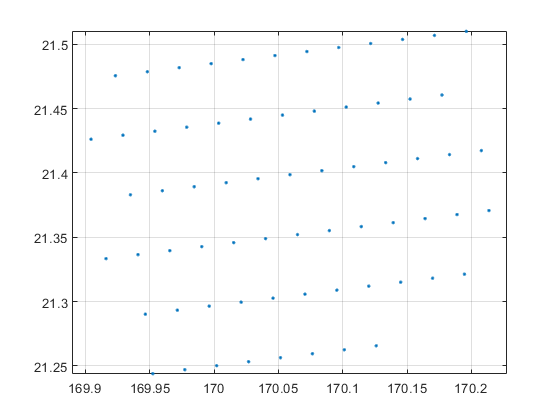

clear all;close all;
% lidar=load('C:\Users\sgrc-325\OneDrive - 國立成功大學 National Cheng Kung University\桌面\readSerial_line\Data 12-15-2023_14.53.txt');
% lidar=load('C:\Users\sgrc-325\OneDrive - 國立成功大學 National Cheng Kung University\桌面\readSerial_line\Lidarlog_20231215_15.7.txt');
% lidar=load('C:\Users\sgrc-325\OneDrive - 國立成功大學 National Cheng Kung University\桌面\readSerial_line\Lidarlog_20231215_15.26.txt');
% lidar=load('C:\Users\sgrc-325\OneDrive - 國立成功大學 National Cheng Kung University\桌面\readSerial_line\Lidarlog_20231215_15.42.txt');

% lidar=load(['C:\Users\sgrc-325\OneDrive - 國立成功大學 National Cheng Kung University\桌面\readSerial_line\' ...
%     'Lidarlog_20231221_17.13.txt']);

% lidar=load(['C:\Users\sgrc-325\OneDrive - 國立成功大學 National Cheng Kung University\桌面\readSerial_line\' ...
%     'Lidarlog_2024118_10.59_imu10hz.txt']);

lidar=load(['C:\Users\sgrc-325\Desktop\readSerial_line\' ...
    'Lidarlog_2024118_11.7_imu100hz.txt']);

t=lidar(:,1);
ang=lidar(:,2);
dis=lidar(:,3);
qua=lidar(:,4);
% f=lidar(:,5);
acc=lidar(:,[6:8]);
gyr=lidar(:,[9:11]);

[a1 ~]=size(lidar);
x(a1,1)=zeros;
y(a1,1)=zeros;
for i=1:a1
    x(i)=dis(i)*cos(ang(i)*-1/180*pi);
    y(i)=dis(i)*sin(ang(i)*-1/180*pi);
end
plot(x,y,'.')
grid on
axis equal


localf=1/((t(end)-t(1))/a1)

localf = 66.0471

timelengh=(t(end)-t(1))

timelengh = 318.2730


std(acc)

ans = 	1.0e+-3 *

    0.5978    0.4570    0.5579


std(gyr)

ans =     0.0584    0.0440    0.0666
